clear all

[pathsSpikes tmp] = ReadPCAPaths('D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\spikes');

[HIP] = ReadUnitTable("A2",2,'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Unit_Table_HIP_Simplified_Enero_2024.xlsx');

[pathsSpikesPCA] = pathsPCA(tmp,pathsSpikes,HIP);


[BST, SPK, SPK9] = ExtractMatFiles(HIP,pathsSpikesPCA);


y1 = 0.250;
y2 = 0.650;


for i = 1:1:size(BST,1)
    ODDTrialIndex = zeros(80,1);
    CTRTrialIndex = zeros(160,1);
    STDTrialIndex = zeros(80,1);
    AllSTDTrialIndex = zeros(360,1);
    n = 1;
    m = 1;
    k = 1;
    p = 1;
    s = 0;
    for j = 1:1:1600
       if isempty(cell2mat(BST(i).bst.Epocs.Values.type(j,1)))
           s = s + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            ODDtrials(n,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            ODDTrialIndex(n,1) = j;
            n = n + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC');
            CTRtrials(m,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            CTRTrialIndex(m,1) = j;
            m = m + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.Block(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'STD')
            STDtrials(k,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            STDTrialIndex(k,1) = j;
            k = k + 1;
       end

       if contains(string(BST(i).bst.Epocs.Values.Block(j,1)),'ODD') && isempty(cell2mat(BST(i).bst.Epocs.Values.type(j,1)))
            AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
            AllSTDTrialIndex(p,1) = j;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.Block(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'STD')
           AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.stim(j,1) + 1;
           AllSTDTrialIndex(p,1) = j;
           p = p + 1;
        end
    end

    ODDTrialIndexS = struct('ODDTrialIndex', ODDTrialIndex);
    CTRTrialIndexS = struct('CTRTrialIndex', CTRTrialIndex);
    STDTrialIndexS = struct('STDTrialIndex', STDTrialIndex);
    AllSTDTrialIndexS = struct('AllSTDTrialIndex', AllSTDTrialIndex);

    ODDTrialsS = struct('ODDtrials', ODDtrials);
    CTRTrialsS = struct('CTRtrials', CTRtrials);
    STDTrialsS = struct('STDtrials', STDtrials);
    AllSTDTrialsS = struct('AllSTDtrials', AllSTDtrials);

    ODDTrialIndexComplete(:,i) = ODDTrialIndexS;
    CTRTrialIndexComplete(:,i) = CTRTrialIndexS;
    STDTrialIndexComplete(:,i) = STDTrialIndexS;
    AllSTDTrialIndexComplete(:,i) = AllSTDTrialIndexS;

    ODDTrialsComplete(:,i) = ODDTrialsS;
    CTRTrialsComplete(:,i) = CTRTrialsS;
    STDTrialsComplete(:,i) = STDTrialsS;
    AllSTDTrialsComplete(:,i) = AllSTDTrialsS;
end

for ii = 1:size(BST,1)
    a = 1;
    spksWindow = [];
    for iii = 1:size(BST(ii).bst.Spikes(:,4).RasterSW,1)
            if BST(ii).bst.Spikes(iii,4).RasterSW > HIP.x1(ii)/1000 && BST(ii).bst.Spikes(iii,4).RasterSW < HIP.x2(ii)/1000
                spksWindow(a,1) = BST(ii).bst.Spikes(iii,3).TrialIdx;
                a = a + 1;
            end
    end

    spksWindowStruct = struct('spksWindow', spksWindow);
    spksWindowComplete(:,ii) = spksWindowStruct;  
end

AllSTD = NaN(size(BST,1)*2,400);
AllDEV = NaN(size(BST,1)*2,400);
AllCTR = NaN(size(BST,1)*2,400);

for ii = 1:size(BST,1)
    for iii = 1:size(ODDTrialIndexComplete(ii).ODDTrialIndex,1)
        spksDEV(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == ODDTrialIndexComplete(ii).ODDTrialIndex(iii,1)));
    end
end

for ii = 1:size(BST,1)
    for iii = 1:size(CTRTrialIndexComplete(ii).CTRTrialIndex,1)
        spksCTR(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == CTRTrialIndexComplete(ii).CTRTrialIndex(iii,1)));
    end
end

for ii = 1:size(BST,1)
    for iii = 1:size(STDTrialIndexComplete(ii).STDTrialIndex,1)
        spksSTD(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == STDTrialIndexComplete(ii).STDTrialIndex(iii,1)));
    end
end

for ii = 1:size(BST,1)
    for iii = 1:720
        AllspksSTD(iii,ii) = numel(find(spksWindowComplete(ii).spksWindow(:,1) == AllSTDTrialIndexComplete(ii).AllSTDTrialIndex(iii,1)));
    end
end


for j = 1:size(BST,1)
    ODDTrialsComplete(j).ODDtrials(:,2)= spksDEV(:,j);
end

for j = 1:size(BST,1)
    CTRTrialsComplete(j).CTRtrials(:,2)= spksCTR(:,j);
end

for j = 1:size(BST,1)
    STDTrialsComplete(j).STDtrials(:,2)= spksSTD(:,j);
end

for j = 1:size(BST,1)
    AllSTDTrialsComplete(j).AllSTDtrials(1:720,2)= AllspksSTD(1:720,j);
end


for i =1:size(BST,1)
    for j = 1:360 
        AllSTD(i,AllSTDTrialsComplete(i).AllSTDtrials(j,1)) = AllSTDTrialsComplete(i).AllSTDtrials(j,2);
    end
        
    for j = 1:40 
        AllDEV(i,ODDTrialsComplete(i).ODDtrials(j,1)) = ODDTrialsComplete(i).ODDtrials(j,2);
    end

    for j = 1:80 
        AllCTR(i,CTRTrialsComplete(i).CTRtrials(j,1)) = CTRTrialsComplete(i).CTRtrials(j,2);
    end
end
for i = 1:size(BST,1)
    for j = 361:720
        AllSTD(i+size(BST,1),AllSTDTrialsComplete(i).AllSTDtrials(j,1)) = AllSTDTrialsComplete(i).AllSTDtrials(j,2);
    end
   
    for j = 41:80 
        AllDEV(i+size(BST,1),ODDTrialsComplete(i).ODDtrials(j,1)) = ODDTrialsComplete(i).ODDtrials(j,2);
    end

    for j = 81:160 
        AllCTR(i+size(BST,1),CTRTrialsComplete(i).CTRtrials(j,1)) = CTRTrialsComplete(i).CTRtrials(j,2);
    end
end

cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Spikes per trial Matrix';
save('AllSTD.mat','AllSTD')
save('AllDEV.mat','AllDEV')
save('AllCTR.mat','AllCTR')

cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\First 10 STD';

ALLSTDmean = nanmean(AllSTD);
ALLDEVmean = nanmean(AllDEV);
ALLCTRmean = nanmean(AllCTR);

AllSTDmeanNorm = ALLSTDmean./max(ALLSTDmean);
Trials = (1:400);
%  n = 0;
STDTotalmean = nanmean(AllSTDmeanNorm)

STDTotalmean = 0.4738

SEM = std(AllSTDmeanNorm)./sqrt(length(AllSTDmeanNorm))

SEM = 0.0071

SEM_v = ones(1,n)*SEM;
figure
AllSTDmeanNorm(1:n)

ans =     0.7893    0.4179    0.4179    0.7080    0.6152    0.5223    0.5920    0.4875    0.5455    0.4991    0.4295    0.5223    0.2205    0.4875    0.4375    0.4000    0.5687    0.5687    0.3482    0.4062    0.4062    0.5223    0.4875    0.4432    0.6384    0.5804    0.6500    0.4643    0.5875    0.7830    0.4295    0.3693    0.5223    0.4759    0.4179    0.3693    0.4062    0.8396    0.7534    0.3830    0.6152    0.5107    0.2902    0.3598    0.3714    0.6057    0.3482    0.8241    0.3598    0.6795


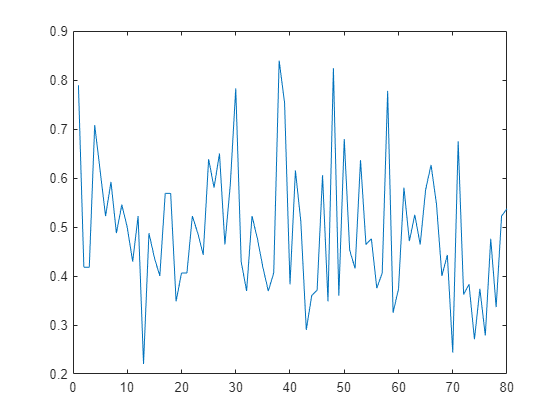

plot(Trials(1:n), AllSTDmeanNorm(1:n))

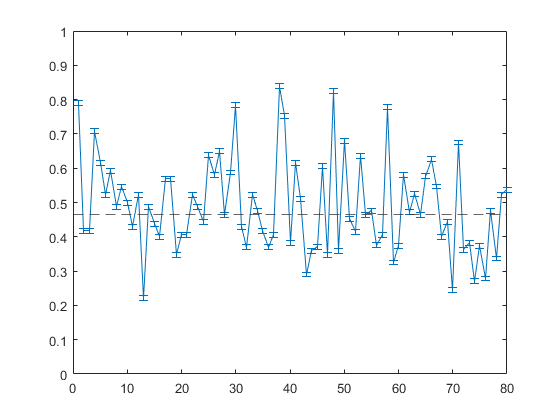

errorbar(Trials(1:n), AllSTDmeanNorm(1:n),SEM_v)
%scatter(Trials(1:10), AllSTDmeanNorm(1:10),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
hold on 
%plot(Trials(1:10), AllSTDmeanNorm(1:10))
yline(mean(AllSTDmeanNorm(200:400)),'--')
xlim([0 n])
ylim([0 1])
% title ('CA1 Random CSI Sig')


saveas(gcf,'DG_First_20_STD.tif');
saveas(gcf,'DG_First_20_STD.fig');
saveas(gcf,'DG_First_20_STD.pdf');
saveas(gcf,'DG_First_20_STD.eps');